# **RT-QIBC analysis**

**FarRed1: chromatin-bound protein stain**

**FarRed2: EdU**

**YFP1: APC/C reporter intensity (residual after preextraction)**

**POI(:,2): APC/C inactivation time**

## **Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\';
impath = fullfile(dataDir,'C226_Images');
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
global framesPerHr numFrames conditions;
conditions = {
        'TIM no dox',2,2:4,1:9,[0 0 0],'Dox-','TIM','DMSO'; %1      
        'TIM dox',2,5:11,1:9,[0 0 0],'Dox+','TIM','DMSO'; %1 
        'TIM ATRi',7,2:4,1:9,[0 0 0],'Dox-','TIM','ATRi'; %1 

    };



load([ dataDir filesep 'C226_data.mat'],'S');
% S = loadData(conditions, dataDir);
framesPerHr = 60/12;
frameDrugAdded = 0;
frameEdU = 0;
timeStart = 1.5;
folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};

**Set thresholds based on treatment 1**

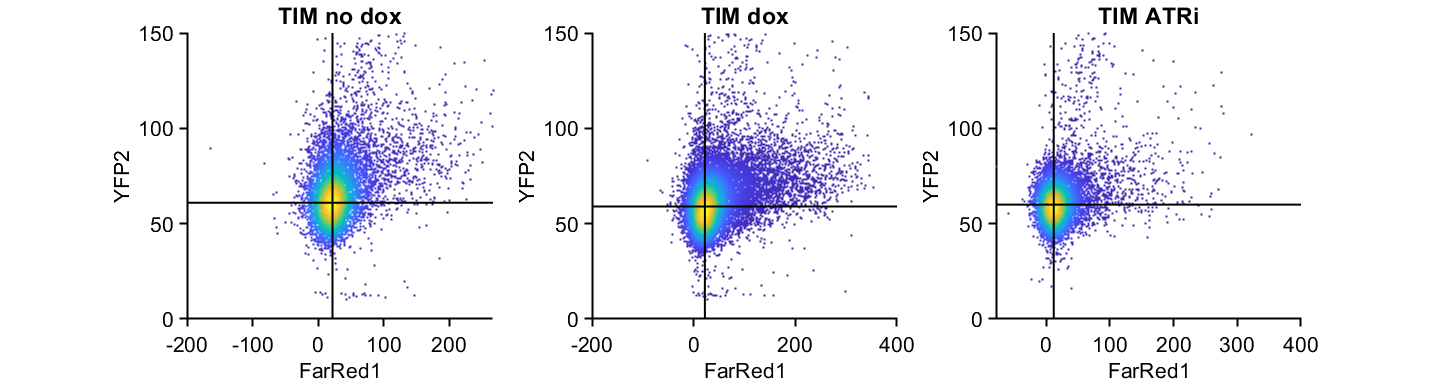

conds=[1 2 3];
f1 = figure('Units', 'Inches', 'Position', [0, 0, 5*length(conds), 4]);

for i = 1:length(conds)
    
    cond = conds(i);
    xval = 'FarRed1';
    yval = 'YFP2';
    
    xdata = S(cond).(xval) - S(cond).FarRed1cyt;
    ydata = S(cond).(yval) ;
   
    inds = S(cond).FarRed1 < 500 & S(cond).YFP3 < 7 & log2(S(cond).dna) < 21.5 & isnan(S(cond).POI(:,2)) &  ydata < 150 ;
    xdata = xdata(inds);
    ydata = ydata(inds);
    
    
    [kval,xv]=ksdensity(xdata,-200:1:400);
    modeX=xv(find(kval==max(kval),1,'first'));
    [kval,xv]=ksdensity(ydata,-200:1:400);
    modeY=xv(find(kval==max(kval),1,'first'));
    S(cond).threshSig = prctile(xdata,95);
    S(cond).threshEdU = prctile(ydata,95);
%     S(cond).medSig = nanmedian(xdata);
    S(cond).medSig = modeX;
%     S(cond).medEdU = nanmedian(ydata);
    S(cond).medEdU = modeY;
    S(cond).threshSigCorr = prctile(xdata,95)  - S(cond).medSig;
    S(cond).threshEdUCorr = prctile(ydata,95) - S(cond).medEdU;    
      
    S(cond+1).threshSig = prctile(xdata,95);
    S(cond+1).threshEdU = prctile(ydata,95);
%     S(cond+1).medSig = nanmedian(xdata);
    S(cond+1).medSig = modeX;
%     S(cond).medEdU = nanmedian(ydata);
    S(cond+1).medEdU = modeY;  
    S(cond+1).threshSigCorr = prctile(xdata,95)  - S(cond+1).medSig;
    S(cond+1).threshEdUCorr = prctile(ydata,95) - S(cond+1).medEdU;    
   
    S(cond+2).threshSig = prctile(xdata,95);
    S(cond+2).threshEdU = prctile(ydata,95);
%     S(cond+2).medSig = nanmedian(xdata);
    S(cond+2).medSig = modeX;
%     S(cond).medEdU = nanmedian(ydata);
    S(cond+2).medEdU = modeY;  
    S(cond+2).threshSigCorr = prctile(xdata,95)  - S(cond+2).medSig;
    S(cond+2).threshEdUCorr = prctile(ydata,95) - S(cond+2).medEdU;    
%     
    figure(f1)
    subplot(1,length(conds),i)
    dscatter(xdata,ydata)
%     hline(S(cond).threshEdU,'k');vline(S(cond).threshSig,'k');
    hline(S(cond).medEdU,'k');vline(S(cond).medSig,'k');

    ylabel(yval);xlabel(xval);
    title(conditions(cond,1))
    
    
    xdata = S(cond).(xval) - S(cond).FarRed1cyt;
    ydata = S(cond).(yval) ;
    S(cond).signalCorr = xdata - S(cond).medSig;
    S(cond).eduCorr = ydata - S(cond).medEdU;

    xdata = S(cond+1).(xval) - S(cond+1).FarRed1cyt;
    ydata = S(cond+1).(yval) ;          
    S(cond+1).signalCorr = xdata - S(cond+1).medSig;
    S(cond+1).eduCorr = ydata - S(cond+1).medEdU;

    xdata = S(cond+2).(xval) - S(cond+2).FarRed1cyt;
    ydata = S(cond+2).(yval) ;          
    S(cond+2).signalCorr = xdata - S(cond+2).medSig;
    S(cond+2).eduCorr = ydata - S(cond+2).medEdU;     

end

Settings thresholds based on 95% (with a removal of EdU positive cells by arb threshold)

**Set thresholds based on treatment 1**

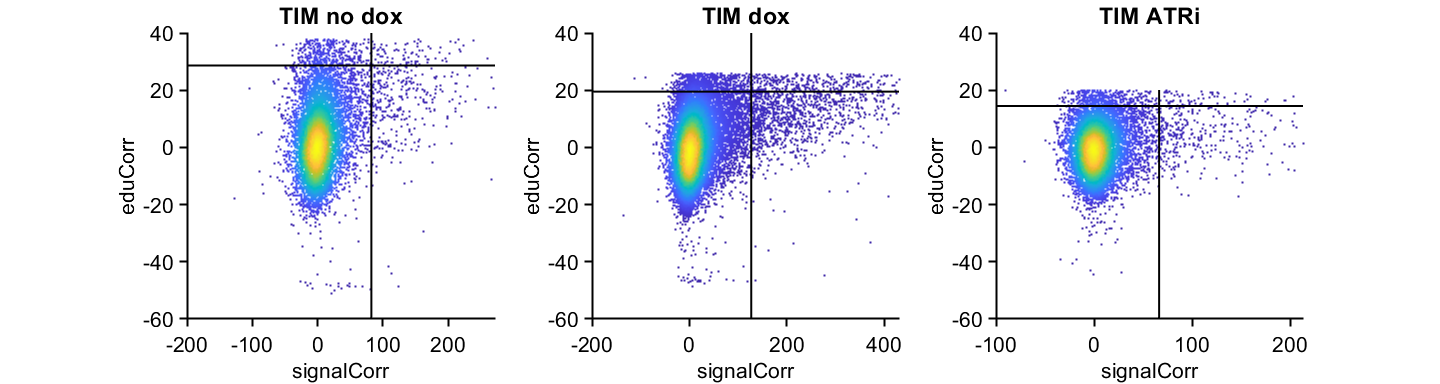

conds=[1 2 3];
f2 = figure('Units', 'Inches', 'Position', [0, 0, 5*length(conds), 4]);

for i = 1:length(conds)
    
    cond = conds(i);
    xval = 'signalCorr';
    zval = 'eduCorr';
    
    xdata = S(cond).(xval);
     zdata = S(cond).(zval) ;
   
    inds = S(cond).YFP3 < 7 & log2(S(cond).dna) < 21.5 & isnan(S(cond).POI(:,2)) &  S(cond).eduCorr < S(cond).threshEdUCorr ;
    xdata = xdata(inds);
    zdata = zdata(inds);
    
    inds = xdata < prctile(xdata, 99.5);
    xdata = xdata(inds);
    zdata = zdata(inds);
    
    
    S(cond).threshPCNA = prctile(zdata,95);
    S(cond).medPCNA = nanmedian(zdata);
       
%     S(cond+1).threshPCNA = prctile(zdata,95);
%     S(cond+1).medPCNA = nanmedian(zdata);
%     
 
    figure(f2)
    subplot(1,length(conds),i)
    dscatter(xdata,zdata)
    ylabel(zval);xlabel(xval);
%     xlim([-200 1000])
%     ylim([-100 1000])
            hline(S(cond).threshPCNA,'k');vline(S(cond).threshSigCorr,'k');

    title(conditions(cond,1))
end

Settings thresholds based on 95% (with a removal of EdU positive cells by arb threshold)

**Load data into table**

conds=[1:3];
poiAligned=2;
offset=0;

dfTotal = table();

gateVals = {{},{},{},{},{},{},{},{},{},{}};
rangeVals = {{[]},{[]},{[]},{[]},{[]},{[]},{[]},{[]}};

for i=1:length(conds)
   % ind = true(size(S(conds(i)).sigNuc(:,1))) ;
    ind = S(conds(i)).dna< 2^22 & S(conds(i)).YFP3 < 15;
    time=(numFrames-(S(conds(i)).POI(ind,poiAligned)-offset))/framesPerHr;
    cdt1=(S(conds(i)).sigNuc(ind,end));
    EdU=(S(conds(i)).eduCorr(ind));
    stain=(S(conds(i)).signalCorr(ind));
    %stain=(S(conds(i)).FarRed1(ind));
   
    gates = gateVals{i};
    for j=1:length(gates)
        %gateData = S(conds(i)).(gates{j})(ind);
        gateData = S(conds(i)).(gates{j})(ind,end);
        inds = gateData < rangeVals{i}{j}(2) & gateData > rangeVals{i}{j}(1);
        time = time(inds);
        cdt1 = cdt1(inds);
        EdU = EdU(inds);
        stain = stain(inds);
    end
    
    inds = time >= 1 &  time <= 3;
    time = time(inds);
    cdt1 = cdt1(inds);
    EdU = EdU(inds);
    stain = stain(inds);
   
    cdt1(cdt1<0.0001) = .0001;
%     EdU(EdU<0.0001) = .0001;
%     stain(stain<0.0001) = .0001;
    EdUNorm = EdU./(stain);

    antibody = repmat(categorical(conditions(conds(i),7)),numel(time),1);
    doxTreatment = repmat(categorical(conditions(conds(i),6)),numel(time),1);
    drugTreatment = repmat(categorical(conditions(conds(i),8)),numel(time),1);
    phase = repmat(categorical("S"),numel(time),1);
    dfTotal = [dfTotal;table(antibody, phase, doxTreatment,drugTreatment,time,cdt1,EdU,stain,EdUNorm)];
end


conds = [1 2 3];
for i=1:length(conds)
    
    ind = S(conds(i)).dna< 2^21.5 & S(conds(i)).YFP3 < 15  & isnan(S(conds(i)).POI(:,2)) & S(conds(i)).eduCorr < S(conds(i)).threshEdUCorr;
    cdt1=(S(conds(i)).sigNuc(ind,end));
    EdU=(S(conds(i)).eduCorr(ind));
    %stain=(S(conds(i)).FarRed1(ind)-S(conds(i)).FarRed1cyt(ind));
    stain=(S(conds(i)).signalCorr(ind));
     
    cdt1(cdt1<0.0001) = .0001;
%     EdU(EdU<0.0001) = .0001;
%     stain(stain<0.0001) = .0001;
    EdUNorm = EdU./(stain);
    
    time = repmat(0,numel(cdt1),1);
    antibody = repmat(categorical(conditions(conds(i),7)),numel(cdt1),1);
    doxTreatment = repmat(categorical(conditions(conds(i),6)),numel(time),1);
    drugTreatment = repmat(categorical(conditions(conds(i),8)),numel(time),1);
    phase = repmat(categorical("G1"),numel(time),1);
    dfTotal = [dfTotal; table(antibody,phase, doxTreatment,drugTreatment,time,cdt1,EdU,stain,EdUNorm)];
end

dfTotal.treatment = categorical(strcat(string(dfTotal.antibody),{'\'},string(dfTotal.doxTreatment)));

Subset based on cdt1 expression

dfGated = dfTotal((log2(dfTotal.cdt1) > 7  & log2(dfTotal.cdt1) < 10 & dfTotal.doxTreatment == 'Dox+') |...
    dfTotal.doxTreatment == 'Dox-',:);


**comparing ND-Cdt1 expression on EdU linear fit**

ans = 8597

ans = 4545

slopes =     1.9681    0.0839


ratio_int =    22.9148   24.0375


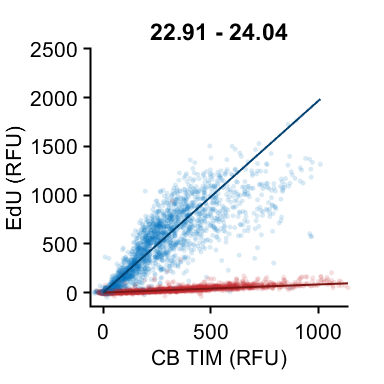

rng(1)
conds={'Dox-','Dox+'};
colors = [0 113 188; 193 39 45]/255;
lincol = [0 65 112; 124 23 20]/255;
colorval = [1 2];
alphas = [.15, .15];

stains = {'TIM'};


ratios = [];
for s=1:length(stains)
    figure('Units', 'Inches', 'Position', [0, 0,4, 4]);
    hold on
    stain_name = stains{s};
    slopes = [];
    xvals = [];
    yvals = [];
    cols = [];
    p=[];
    bs = [];
    %%% Load data into new table
    for i=1:length(conds)
        data = dfGated(dfGated.antibody == stain_name ,:);
        data = data(data.doxTreatment == conds{i} & data.phase == "S",:);
        xdata = (data.stain);
        ydata = (data.EdU);
        
        warning('off')
        b = bootstrp(10,@(x,y)robustfit(x,y,'bisquare',2,'off'), xdata,ydata);
        bs(:,i) = b;
        slopes(i) = robustfit(xdata,ydata,'bisquare',2,'off');
        warning('on')
        inds = xdata < prctile(xdata,99);
        sum(inds)
        if sum(inds) > 2000
            inds = find(inds);
            inds = randsample(inds,2000,false);
        end
%         length(inds)
        xvals = [xvals;xdata(inds)];
        yvals = [yvals; ydata(inds)];
        cols = [cols; repmat(colors(colorval(i),:),length(inds),1)];
        minstain = min(xdata(inds));
        maxstain = max(xdata(inds));
        p(i) = plot([0 maxstain],slopes(i)*[0 maxstain],'Color',lincol(i,:));

    end
    reorder = randperm(length(xvals));
    scatter(xvals(reorder),yvals(reorder),15,cols(reorder,:),'filled','MarkerFaceAlpha',alphas(i))        
    uistack(p,'top')
%     uistack(p(2),'top')

    axis square
    xlabel(['CB ' stain_name ' (RFU)'],'FontSize',16)
    ylabel('EdU (RFU)','FontSize',16)
    xlimits = xlim;
    ylim([min(ydata)-100 2500])
    xlim([min([0 minstain*2]) xlimits(2)])

    slopes
    ratios(s) = slopes(1)/slopes(2);
    
    ratio_int = prctile(bs(:,1)./bs(:,2),[2.5 97.5])

    title(sprintf('%.2f - %.2f',ratio_int(1),ratio_int(2)))
%     
%     ratios(s) = ratio;
    print_pdf([pwd() '\Figs\linear_fit_compare_' stains{s} '.pdf'])

end

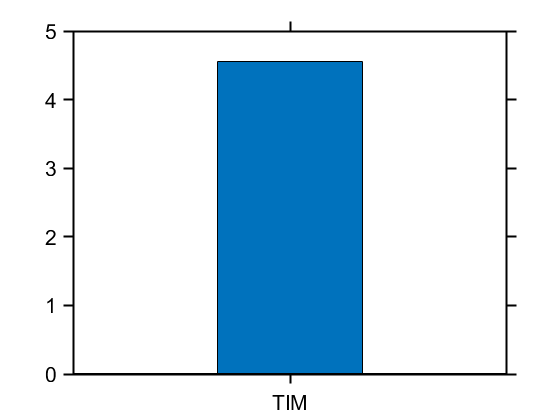


figure,
bar(log2(ratios))
hline(0,'k:')
xticklabels(stains)

writematrix(ratios)

**comparing ND-Cdt1 expression on Cdc45 and EdU**

conds={'Dox-','Dox-','Dox+'};
drugs = {'DMSO','DMSO','DMSO'};
phase = {'G1','S','S'};
names = {'G1','Dox-','Dox+'};
colors = [0 113 188; 193 39 45; 77,175,74]/255;
colorval = [1 2 3];
stains = {'TIM'};
ally = [];
group = [];
index = 0;
outmat = NaN * ones(length(stains),2);
for j = 1:length(stains)
    stain = stains{j};
    stand = median(dfGated.stain(dfGated.antibody == stain & dfGated.doxTreatment == 'Dox-' & dfGated.drugTreatment  == 'DMSO' & dfGated.phase == 'S' ));
    for i=1:length(conds)
        data = dfGated(dfGated.antibody == stain,:);
        data = data(data.doxTreatment == conds{i} & data.drugTreatment == drugs{i} & data.phase == phase{i},:);
        if strcmp(phase{i},'S')
            data = data(data.EdU > 15,:);
        end
        xdata = data.stain/stand;
        
        inds = xdata < prctile(xdata,99.5) & xdata > prctile(xdata,.5);
        xdata = xdata(inds);
        
        if strcmp(names{i}, 'G1')
            xdata = randsample(xdata,3000,false);
        end
                    xdata = randsample(xdata,2000,false);

        index = index + 1;
        ally = [ally; xdata];
        group = [group; (index)*ones(size(xdata))];
        
        if strcmp(names{i}, 'Dox-')
            outmat(j,1) = median(xdata);
        elseif strcmp(names{i},'Dox+')
            outmat(j,2) = median(xdata);
        end
        length(xdata)
    end
    
end

ans = 2000

ans = 2000

ans = 2000

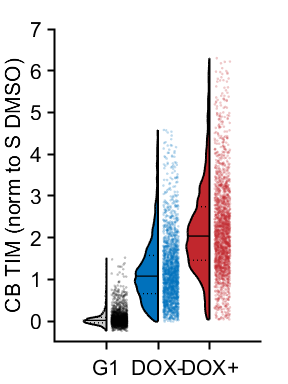


cols = repmat({[.8 .8 .8],colors(1,:),colors(2,:)}',1,1);
groupcol = repmat([0 0 0; colors([1 2 ],:)],1,1);

figure('Units', 'Inches', 'Position', [0, 0, 3, 4])
% h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1],...
%     'xNames',names);
h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1]);
set(h{1},'EdgeColor',[0 0 0],'LineWidth',1.5)
set(h{1},{'FaceColor'},cols) 

hold on
jit = 0.3*rand(size(group)) + .1;
scatter(group+jit, (ally), 4,groupcol(group,:),'filled','MarkerFaceAlpha',.25);
ylabel([ 'CB TIM (norm to S DMSO)'])
% xticks([2 5 8 11 14])
xticklabels({'G1','DOX-','DOX+','ATRi'})
ylim([-.5 7])
% xtickangle(45)


% pbaspect([1 1 1])
print_pdf([pwd() '\Figs\stain_compare_small.pdf'])

**comparing ND-Cdt1 expression on Cdc45 and EdU**

conds={'Dox-','Dox+'};
drugs = {'DMSO','DMSO'};
phase = {'G1','G1'};
names = {'Dox-','Dox+'};
colors = [0 113 188; 193 39 45; 77,175,74]/255;
colorval = [1 2 3];
stains = {'TIM'};
ally = [];
group = [];
index = 0;
outmat = NaN * ones(length(stains),2);
for j = 1:length(stains)
    stain = stains{j};
    stand = median(dfGated.stain(dfGated.antibody == stain & dfGated.doxTreatment == 'Dox-' & dfGated.drugTreatment  == 'DMSO' & dfGated.phase == 'S' ));
    for i=1:length(conds)
        data = dfGated(dfGated.antibody == stain,:);
        data = data(data.doxTreatment == conds{i} & data.drugTreatment == drugs{i} & data.phase == phase{i},:);
        if strcmp(phase{i},'G1')
            data = data(data.EdU < 15,:);
        end
        xdata = data.stain/stand;
        
        inds = xdata < prctile(xdata,99.5) & xdata > prctile(xdata,.5);
        xdata = xdata(inds);
        
        if strcmp(phase{i}, 'G1')
            xdata = randsample(xdata,2000,false);
        end
        
        index = index + 1;
        ally = [ally; xdata];
        group = [group; (index)*ones(size(xdata))];
        
        if strcmp(names{i}, 'Dox-')
            outmat(j,1) = median(xdata);
        elseif strcmp(names{i},'Dox+')
            outmat(j,2) = median(xdata);
        end
        length(xdata)
    end
    
end

ans = 2000

ans = 2000

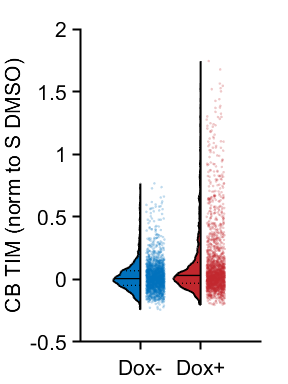


cols = repmat({colors(1,:),colors(2,:)}',1,1);
groupcol = repmat([colors([1 2 ],:)],1,1);

figure('Units', 'Inches', 'Position', [0, 0, 3, 4])
% h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1],...
%     'xNames',names);
h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1]);
set(h{1},'EdgeColor',[0 0 0],'LineWidth',1.5)
set(h{1},{'FaceColor'},cols) 

hold on
jit = 0.3*rand(size(group)) + .1;
scatter(group+jit, (ally), 4,groupcol(group,:),'filled','MarkerFaceAlpha',.25);
ylabel([ 'CB TIM (norm to S DMSO)'])
% xticks([2 5 8 11 14])
xticklabels(names)
ylim([-.5 2])
% xtickangle(45)


% pbaspect([1 1 1])
print_pdf([pwd() '\Figs\stain_compare_small_g1.pdf'])

**look at early S cells TIM no ATRi**

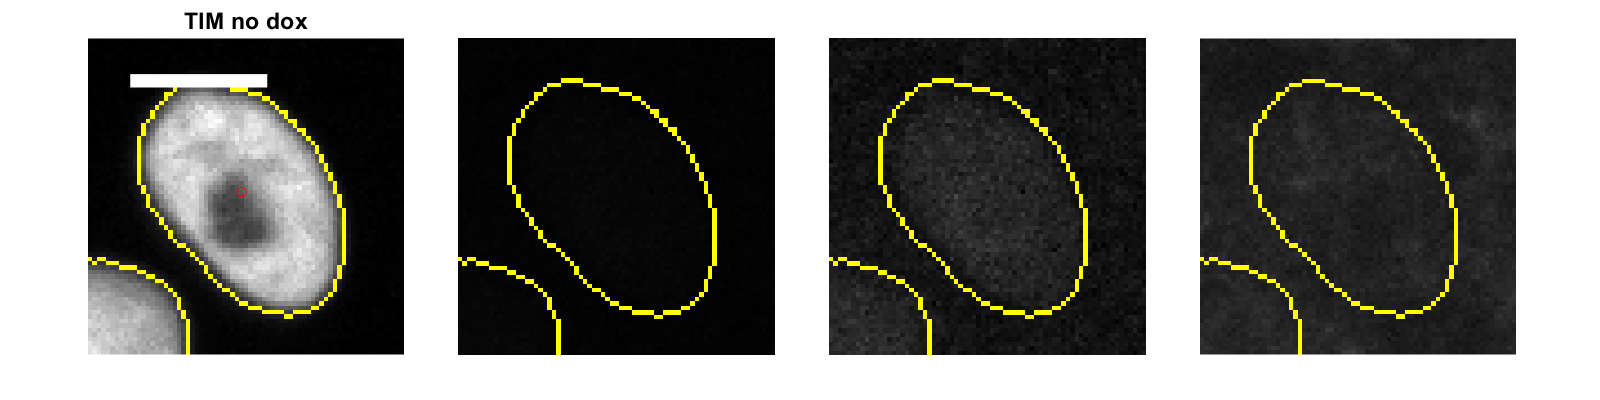

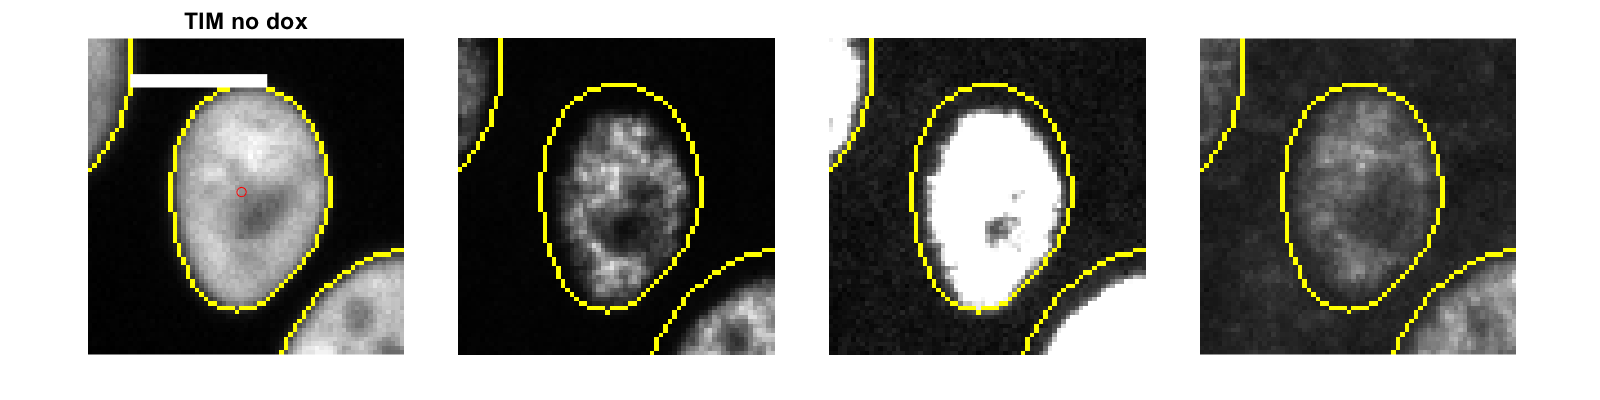

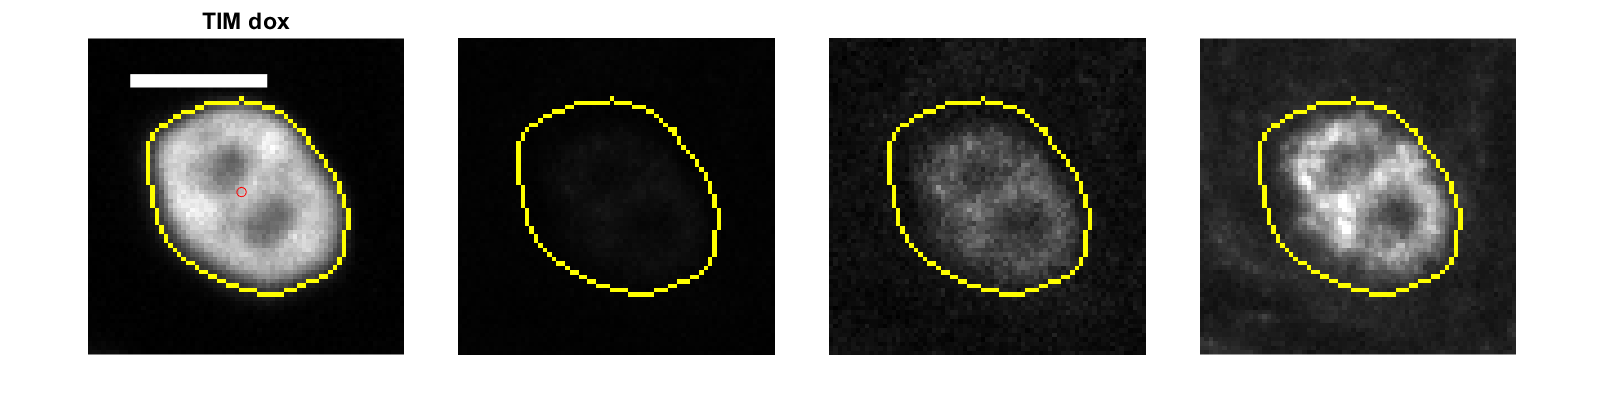

conds=[1 1 2];

sizeBox =35;
max_cells = 1;
gap = 10;
rng(2)
range1high = [0 3000];
range1low  = [0 500];
range2 = [0 1750];

names = conditions;
cellImage(conds, S, max_cells, sizeBox, names, range1high, range1low, range2, gap,impath);

function cellImage(conds, S, max_cells, sizeBox, names, range1high, range1low, range2, gap,impath)

poi_align = 2;
name_cond = {'G1','DMSO','DOX','ATRi'};


for i = 1:length(conds)
    cond = conds(i);
    if i == 1
        ind = S(cond).dna< 2^22 & S(cond).YFP3 < 15  & isnan(S(cond).POI(:,2)) & S(cond).eduCorr < S(conds(i)).threshEdUCorr;
        if mod(cond,2) == 0
            ind = ind & S(cond).sigNuc(:,end) > 2^8;
        end
    else
        ind = S(cond).POI_time(:,poi_align) >= 2 & S(cond).POI_time(:,poi_align) <= 3 & ...
            S(cond).dna< 2^22 & S(conds(i)).YFP3 < 15 & S(cond).eduCorr > S(conds(i)).threshEdUCorr;
        if mod(cond,2) == 0
            ind = ind & S(cond).sigNuc(:,end) > 2^8;
        end
    end
    
    values = S(cond).signalCorr(ind);
    middle_gate = prctile(values,[45 55]);
    ind = ind & S(cond).signalCorr > middle_gate(1) & S(cond).signalCorr < middle_gate(2);
    
        values = S(cond).eduCorr(ind);
    middle_gate = prctile(values,[45 55]);
    ind = ind & S(cond).eduCorr > middle_gate(1) & S(cond).eduCorr < middle_gate(2);
    
    cells = find(ind);
    num_cells = min([max_cells length(cells)]);
    rsamp = randsample(length(cells),num_cells);
    cells = cells(rsamp);
    figure('Position',[0 0 4*400 num_cells*400])
    tiledlayout(num_cells,4,'TileSpacing','Compact','Padding','Compact')
    colormap gray
    ax = [];
    for j = 1:length(cells)
        dims = [1 3];
        imsize = sizeBox*2 +1;
        grid_im = uint8(zeros(dims(1)*imsize + (dims(1) - 1) * gap,dims(2)*imsize + 2*gap,3));
        png_alpha = grid_im(:,:,1);
        
        c = cells(j);
        shot = [num2str(S(cond).fixedRow(c)),'_',num2str(S(cond).fixedCol(c)),'_',num2str(S(cond).fixedSite(c))];
        x = (S(cond).x(c))*1;
        y = (S(cond).y(c))*1;
        signal = (S(cond).signalCorr(c));
        
%         out_folder = fullfile('F:\Data\C-Cdt1\Figures\Dryad\Data\C226_Images',shot,'\');
%         mkdir(out_folder)
%         copyfile(fullfile(impath,shot,[shot '_DAPI__round1.tif']),fullfile(out_folder,[shot '_DAPI__round1.tif']))
%         copyfile(fullfile(impath,shot,[shot '_YFP__round2.tif']),fullfile(out_folder,[shot '_YFP__round2.tif']))
%         copyfile(fullfile(impath,shot,[shot '_FarRed__round1.tif']),fullfile(out_folder,[shot '_FarRed__round1.tif']))
%         copyfile(fullfile(impath,shot,[shot '_mask.tif']),fullfile(out_folder,[shot '_mask.tif']))
%         
        im1=imread(fullfile(impath,shot,[shot '_DAPI__round1.tif']));
        im2=imread(fullfile(impath,shot,[shot '_YFP__round2.tif']))*4;
        im3=imread(fullfile(impath,shot,[shot '_FarRed__round1.tif']))*4;
        mask = (imread(fullfile(impath,shot,[shot '_mask.tif'])));
%                 mask = imdilate(mask,strel('disk',1));
        
        
        cropx = x + [-sizeBox sizeBox];
        cropx = round(min(max(cropx,0),size(im1,1)));
        xmin = cropx(1);
        width = cropx(2) - cropx(1);
        cropy = y + [-sizeBox sizeBox];
        cropy = round(min(max(cropy,0),size(im1,2)));
        ymin=cropy(1);
        height = cropy(2) - cropy(1);
        im1crop= imcrop(im1,[xmin ymin width height]);
        im2crop= imcrop(im2,[xmin ymin width height]);
        im3crop= imcrop(im3,[xmin ymin width height]);
        maskcrop = imcrop(mask,[xmin ymin width height]);
        %         fillcrop = imcrop(fillMask,[xmin ymin width height]);
        
        %%% DAPI
        ax(1) = nexttile;
        temp = mat2gray(im1crop);
        outIm = imoverlay(temp,maskcrop,'y');
        axis square
        imshow(outIm);
        hold on
        scatter(mean(cropx)-min(cropx),mean(cropy)-min(cropy),50,'or');
        t=title([names{cond,1}],'FontSize',6);
        
        pixel_size = .325; %um/pixel
        bar_length = 10/pixel_size;
        plot([10 ,10  +  bar_length], [10, 10 ],'Color','w','LineWidth',10)
        
        
        top_left = [(1 - 1)*(gap+imsize), (1 - 1)*(gap+imsize)];
        grid_im(top_left(1) + (1:imsize),top_left(2) + (1:imsize),:) = outIm;
        png_alpha(top_left(1) + (1:imsize),top_left(2) + (1:imsize)) = 1;
        
        % Individual DAPI image
        %         output_name = sprintf('DAPI_%s_%s_cell%d.png',[names{cond,1}],name_cond{i},c);
        %         imwrite(outIm, [pwd() '\Figs_new\' output_name])
        
        %%% EdU high
        ax(2) = nexttile;
        %         subplot(num_cells,4,2 + 4*(i-1))
        temp = mat2gray(im2crop,range1high);
        outIm = imoverlay(temp,maskcrop,'y');
        axis square
        imshow(outIm);
        hold on
        
        top_left = [(1 - 1)*(gap+imsize), (2 - 1)*(gap+imsize)];
        grid_im(top_left(1) + (1:imsize),top_left(2) + (1:imsize),:) = outIm;
        png_alpha(top_left(1) + (1:imsize),top_left(2) + (1:imsize)) = 1;
        
        % Individual EdU image
        %         output_name = sprintf('EdU_%s_%s_cell%d.png',[names{cond,1}],name_cond{i},c);
        %         imwrite(outIm, [pwd() '\Figs_new\' output_name])
        
        
        %%% EdU low
        ax(3) = nexttile;
        %         subplot(num_cells,4,2 + 4*(i-1))
        temp = mat2gray(im2crop,range1low);
        outIm = imoverlay(temp,maskcrop,'y');
        axis square
        imshow(outIm);
        hold on
        
        %%% Stain
        ax(4) = nexttile;
        %         subplot(num_cells,4,3 + 4*(i-1))
        temp = mat2gray(im3crop,range2);
        outIm = imoverlay(temp,maskcrop,'y');
        imshow(outIm);
        axis square
        %         imagesc(im3crop,range2)
        hold on
        linkaxes(ax)
        
        top_left = [(1 - 1)*(gap+imsize), (3 - 1)*(gap+imsize)];
        grid_im(top_left(1) + (1:imsize),top_left(2) + (1:imsize),:) = outIm;
        png_alpha(top_left(1) + (1:imsize),top_left(2) + (1:imsize)) = 1;
        
        % Individual stain image
        %         output_name = sprintf('stain_%s_%s_cell%d.png',[names{cond,1}],name_cond{i},c);
        %         imwrite(outIm, [pwd() '\Figs_new\' output_name])
        
        
        output_name = sprintf('%s_%s_cell%d.pdf',[names{cond,1}],name_cond{i},c);
        %         print([pwd() '\Figs_new\' output_name])
        print_pdf([pwd() '\Figs\' output_name])
        
        output_name = sprintf('%s_%s_cell%d.png',[names{cond,1}],name_cond{i},c);
        imwrite(grid_im, [pwd() '\Figs\' output_name],'Alpha',double(png_alpha),'Mode','lossless')
    end
end
end
